# PUCCH资源映射

PUCCH（物理上行控制信道）主要用于承载控制信息，如调度请求、确认和CSI反馈，以请求分配上行资源、确认接收到的数据、报告信道质量，进而确保网络的高效运行和优质的通信服务。

- ACK/NACK反馈：PUCCH用于传输接收到的数据包的确认（ACK，Acknowledgment）或否定（NACK，Negative Acknowledgment）反馈。这是为了告知发送端是否成功接收了数据包，以便发送端可以相应地采取措施，如重传数据。

- Scheduling Request（调度请求）：终端可以使用PUCCH发送调度请求，以请求分配更多的上行资源，以便传输数据。这对于支持低延迟和高带宽需求的应用非常重要。

- 信道质量反馈：PUCCH也用于上行链路的信道质量反馈，以便基站能够根据用户设备的信道状态进行调度和资源分配。这有助于提高网络的效率和性能。

## 1 载波配置

clear;
clc;
close all;

% Carrier configuration
carrier = nrCarrierConfig;
carrier.NCellID = 2;                    % Cell identity
carrier.SubcarrierSpacing = 30;         % Carrier/BWP Subcarrier spacing
carrier.CyclicPrefix = 'normal';        % Cyclic prefix
carrier.NSlot      = 0;                 % Slot counter
carrier.NFrame     = 0;                 % Frame counter
carrier.NStartGrid = 0;                 % Carrier offset
carrier.NSizeGrid  = 51;                % Size of carrier in RB

resGrid = nrResourceGrid(carrier);

beta_dmrs = 3;   % only for display.

## 2 PUCCH资源配置

## 2.1 UCI bit

For format 0, you must specify a binary-valued column vector, a one-element cell array, or a two-element cell array.

- When you specify this value as a binary-valued column vector or a one-element cell array, the UCI bits are assumed to be hybrid automatic repeat request acknowledgment (HARQ-ACK) bits.

- When you specify this value as a two-element cell array, the first element is assumed to have HARQ-ACK bits, and the second element is assumed to have scheduling request (SR) bit.

For format 1, you must specify a binary-valued column vector or a one-element cell array. This argument must contain HARQ-ACK bits or SR bits. To transmit only positive SR bit, specify this argument as `[0]` or `{0}`.

For formats 2, 3, and 4, you must specify a binary-valued column vector or a one-element cell array. This argument must contain a codeword of encoded UCI bits.

% UCI bit
ack = [1;1];                    % HARQ-ACK bits  [] | [bit0] | [bit0;bit1]  1:ACK 0:NACK
sr = [];                        % SR bit [] | 1 | 0   [] : PUCCH transmission without SR  1: positive SR    0: negative SR
uciBits_f0 = {ack,sr}; 
uciBits_f1 = ack;

uciBits_f2 = randi([0 1],15,1);
uciBits_f3 = randi([0 1],15,1);
uciBits_f4 = randi([0 1],15,1);

### 2.2 PUCCH format

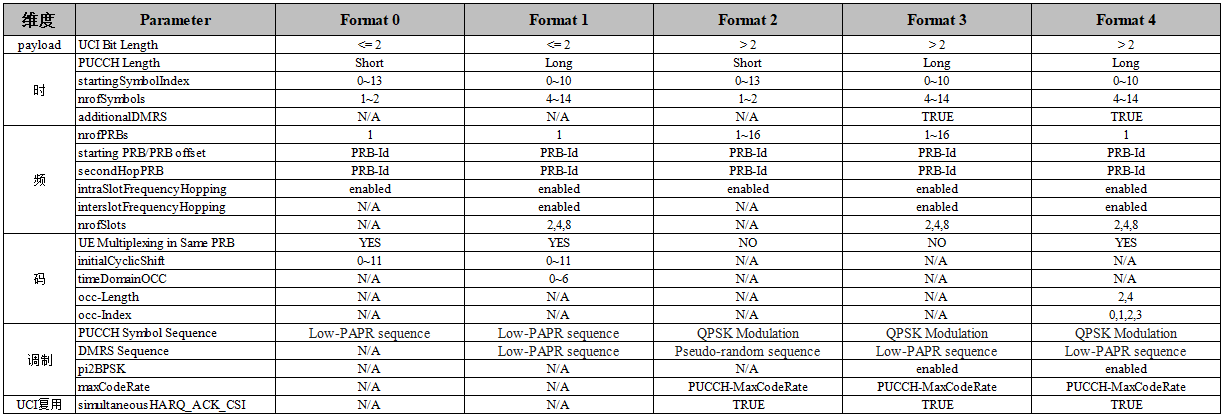

**PUCCH format0**

% PUCCH configuration
pucch_f0 = nrPUCCH0Config;
pucch_f0.NSizeBWP = [];
pucch_f0.NStartBWP = [];
pucch_f0.SymbolAllocation = [0 2];        % [symbol start, symbol length 1/2]
pucch_f0.PRBSet = 0;
pucch_f0.FrequencyHopping = 'neither';    % 'neither' | 'intraSlot' | 'interSlot'
pucch_f0.SecondHopStartPRB = 50;          % Enable interslot frequency hopping, config SecondHopStartPRB.
pucch_f0.GroupHopping = 'neither';        % PUCCH-ConfigCommon: 'neither' | 'enable' | 'disable'
pucch_f0.HoppingID = [];                  % PUCCH-ConfigCommon                
pucch_f0.InitialCyclicShift = 0;

sym = nrPUCCH(carrier,pucch_f0,uciBits_f0);
[ind,~] = nrPUCCHIndices(carrier,pucch_f0);
resGrid(ind) = sym;

% figure;
% scatterplot(sym);
sym_table = array2table(sym)

sym_table = 24×1 table
           sym       
    _________________

    -0.70711-0.70711i
    -0.25882+0.96593i
     0.25882+0.96593i
     0.70711-0.70711i
    -0.25882+0.96593i
     0.96593-0.25882i
    -0.70711+0.70711i
    -0.96593-0.25882i
    -0.25882-0.96593i
     0.70711-0.70711i
    -0.96593-0.25882i
    -0.25882-0.96593i
    -0.70711-0.70711i
     0.70711+0.70711i
     0.70711-0.70711i
    -0.70711+0.70711i


**PUCCH format1**

% PUCCH configuration
pucch_f1 = nrPUCCH1Config;
pucch_f1.NSizeBWP = [];
pucch_f1.NStartBWP = [];
pucch_f1.SymbolAllocation = [0 14];        % [symbol start, symbol length 4-14]
pucch_f1.PRBSet = 5;
pucch_f1.FrequencyHopping = 'neither';     % 'neither' | 'intraSlot' | 'interSlot'
pucch_f1.SecondHopStartPRB = 45;           % Enable interslot frequency hopping, config SecondHopStartPRB.
pucch_f1.GroupHopping = 'neither';         % PUCCH-ConfigCommon: 'neither' | 'enable' | 'disable'
pucch_f1.HoppingID = [];                   % PUCCH-ConfigCommon                
pucch_f1.InitialCyclicShift = 0;
pucch_f1.OCCI = 0;

sym = nrPUCCH(carrier,pucch_f1,uciBits_f1);
[ind,~] = nrPUCCHIndices(carrier,pucch_f1);

dmrs_sym = beta_dmrs*nrPUCCHDMRS(carrier,pucch_f1);
dmrs_ind = nrPUCCHDMRSIndices(carrier,pucch_f1);

resGrid(ind) = sym;
resGrid(dmrs_ind) = dmrs_sym;

**PUCCH format2**

% PUCCH configuration
pucch_f2 = nrPUCCH2Config;
pucch_f2.NSizeBWP = [];
pucch_f2.NStartBWP = [];
pucch_f2.SymbolAllocation = [12 2];        % [symbol start, symbol length 4-14]
pucch_f2.PRBSet = [10 11];
pucch_f2.FrequencyHopping = 'neither';     % 'neither' | 'intraSlot' | 'interSlot'
pucch_f2.SecondHopStartPRB = 40;           % Enable interslot frequency hopping, config SecondHopStartPRB.
pucch_f2.NID = []; 
pucch_f2.RNTI = 1;                         % UE RNTI
pucch_f2.NID0 = [];

[ind,info] = nrPUCCHIndices(carrier,pucch_f2);
uciCodeword = nrUCIEncode(uciBits_f2,info.G);
sym = nrPUCCH(carrier,pucch_f2,uciCodeword);

dmrs_sym = beta_dmrs*nrPUCCHDMRS(carrier,pucch_f2);
dmrs_ind = nrPUCCHDMRSIndices(carrier,pucch_f2);

resGrid(ind) = sym;
resGrid(dmrs_ind) = dmrs_sym;

coderate = length(uciBits_f2)/info.G;
info.coderate = coderate;
info.N_RB_SC = 8;
disp(info)

                G: 64
               Gd: 32
        NREPerPRB: 16
    DMRSSymbolSet: [12 13]
         coderate: 0.2344
          N_RB_SC: 8



**PUCCH format3**

% PUCCH configuration
pucch_f3 = nrPUCCH3Config;
pucch_f3.NSizeBWP = [];
pucch_f3.NStartBWP = [];
pucch_f3.Modulation = 'QPSK';              % 'QPSK' | 'pi/2-BPSK'   
pucch_f3.SymbolAllocation = [0 14];        % [symbol start, symbol length 4-14]
pucch_f3.PRBSet = [20 21];                 % 满足235原则
pucch_f3.FrequencyHopping = 'intraSlot';   % 'neither' | 'intraSlot' | 'interSlot'
pucch_f3.SecondHopStartPRB = 35;           % Enable interslot frequency hopping, config SecondHopStartPRB.
pucch_f3.GroupHopping = 'neither';         % PUCCH-ConfigCommon: 'neither' | 'enable' | 'disable'
pucch_f3.HoppingID = [];                   % PUCCH-ConfigCommon                
pucch_f3.NID = []; 
pucch_f3.RNTI = 1;                         % UE RNTI
pucch_f3.AdditionalDMRS = 1;

[ind,info] = nrPUCCHIndices(carrier,pucch_f3);
uciCodeword = nrUCIEncode(uciBits_f3,info.G);
sym = nrPUCCH(carrier,pucch_f3,uciCodeword);

dmrs_sym = beta_dmrs*nrPUCCHDMRS(carrier,pucch_f3);
dmrs_ind = nrPUCCHDMRSIndices(carrier,pucch_f3);

resGrid(ind) = sym;
resGrid(dmrs_ind) = dmrs_sym;

coderate = length(uciBits_f3)/info.G;
info.coderate = coderate;
info.N_RB_SC = 12;
disp(info)

                G: 480
               Gd: 240
        NREPerPRB: 120
    DMRSSymbolSet: [1 5 8 12]
         coderate: 0.0312
          N_RB_SC: 12



**PUCCH format4**

% PUCCH configuration
pucch_f4 = nrPUCCH4Config;
pucch_f4.NSizeBWP = [];
pucch_f4.NStartBWP = [];
pucch_f4.Modulation = 'QPSK';              % 'QPSK' | 'pi/2-BPSK'   
pucch_f4.SymbolAllocation = [0 14];        % [symbol start, symbol length 4-14]
pucch_f4.PRBSet = 25;
pucch_f4.FrequencyHopping = 'intraSlot';   % 'neither' | 'intraSlot' | 'interSlot'
pucch_f4.SecondHopStartPRB = 30;           % Enable interslot frequency hopping, config SecondHopStartPRB.
pucch_f4.GroupHopping = 'neither';         % PUCCH-ConfigCommon: 'neither' | 'enable' | 'disable'
pucch_f4.HoppingID = [];                   % PUCCH-ConfigCommon
pucch_f4.SpreadingFactor = 2;              % occ-length n2|n4
pucch_f4.OCCI = 0;                         % occ-index must be less than the SpreadingFactor property.
pucch_f4.NID = [];
pucch_f4.RNTI = 1;                         % UE RNTI
pucch_f4.AdditionalDMRS = 0;

[ind,info] = nrPUCCHIndices(carrier,pucch_f4);
uciCodeword = nrUCIEncode(uciBits_f4,info.G);
sym = nrPUCCH(carrier,pucch_f4,uciCodeword);

dmrs_sym = beta_dmrs*nrPUCCHDMRS(carrier,pucch_f4);
dmrs_ind = nrPUCCHDMRSIndices(carrier,pucch_f4);

resGrid(ind) = sym;
resGrid(dmrs_ind) = dmrs_sym;

coderate = length(uciBits_f4)/info.G;
info.coderate = coderate;
info.N_RB_SC = 12/pucch_f4.SpreadingFactor;
disp(info)

                G: 144
               Gd: 72
        NREPerPRB: 144
    DMRSSymbolSet: [3 10]
         coderate: 0.1042
          N_RB_SC: 6



## **3 资源网格显示**

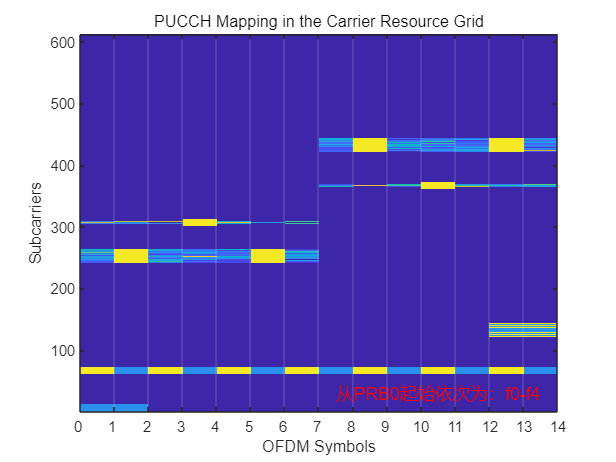

figure;
imagesc(abs(resGrid));
set(gca, 'XLim', [0.5, 14.5]);
set(gca, 'XTick', (0:14)+0.5);
set(gca, 'XTickLabel', (0:14));
set(gca, 'XGrid', 'on');
set(gca, 'GridColor', 'white');
set(gca, 'YDir', 'normal');
xlabel('OFDM Symbols');
ylabel('Subcarriers');
title('PUCCH Mapping in the Carrier Resource Grid');
text(8, 30, '从PRB0起始依次为：f0-f4', 'Color', 'red', 'FontSize', 12);

## 4 附录